`Task 2: FEM approximation of PDE`

We look at the solution of the one dimensional boundary value problem

                    $-(a(x,w)u'(x,w))' = 4\pi^2\cos(2\pi x)$    for $x\in(0,1)$

with $u(0,\cdot)=u(1,\cdot)=0$. We are interested in computing the expected value of the following Quantity of Interest

                                $Q(u(w)) = \int_0^1 u(x,w)dx$.

We use an $I+1$uniform grid $0=x_0<x_1<\ldots<x_I=1$ on $[0,1]$ with uniform spacing $h=x_{i+1}-x_i =\frac{1}{I}$, $i=1,\ldots, I$.

I = 100;
X = linspace(0, 1, I + 1);

Using this grid we can build a piecewise linear FEM approximation,

                                    $u_h(x,w) = \sum_{i=1}^{I-1}\mathbf{u}_{h,i}(w)\varphi_i(x)$,

yielding a tridiagonal linear system for the nodal values, 

                                    $A(w)\mathbf{u}_h(w)=F$,

with 

                            
$$A_{i,i-1}(w) = -\frac{a\left(x_{i-\frac{1}{2}},w\right)}{h^2}$$


                            
$$A_{i,i}(w) = \frac{a\left(x_{i-\frac{1}{2}},w\right) + a\left(x_{i+\frac{1}{2}},w\right)}{h^2}$$


                            
$$A_{i,i-1}(w) = -\frac{a\left(x_{i+\frac{1}{2}},w\right)}{h^2}$$


and $F_i = f(x_i)$. Here we used the notation

                             $x_{i+\frac{1}{2}} = \frac{x_i+x_{i+1}}{2}$     and     $x_{i-\frac{1}{2}} = \frac{x_i+x_{i-1}}{2}$.

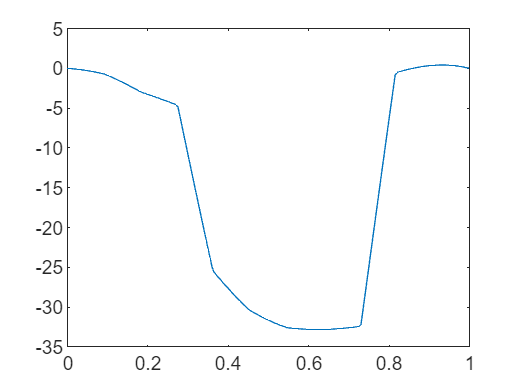

randomfield = 1; % 1 == ccp field
%randomfield = 2; % 2 == for Log normal field
u_h = FEM(I, randomfield);
plot(linspace(0, 1, 2*I+1), u_h);

size(u_h)

ans =    201     1


The integral $Q(u_h)$ can be then computed exactly by a trapezoidal method, yielding

                                    $Q(u_h) = h\sum_{i=1}^{I-1} \mathbf{u}_{h,i}$.

h = 1/I;
Q_uh = h*sum(u_h)

Q_uh =  -29.490498006988446


So now we can sample the quantity of interest $Q(u_h)$ such that we can estimate $\mathbb{E}[Q(u_h)]$ using plain Monte Carlo.